# Alle Opgaver Løst igen ark :)

## Lecture 5

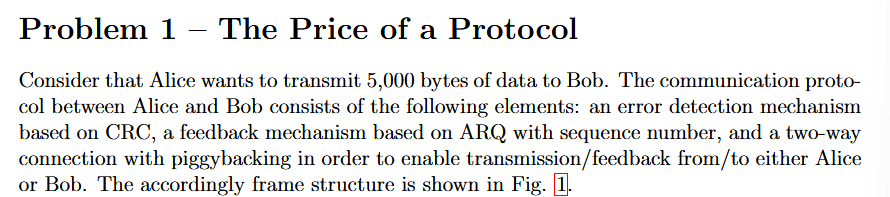

(a) What is the minimum number of frames required to be transmitted by Alice in order to convey the 5,000 bytes of data to Bob?

Solution:

number_frames = ceil(5000/64)% frames :)

number_frames =     79


(b) Consider that the communication channel that connects Alice and Bob supports a data rate of 1 kbit/s. What would be the minimum time required for Alice’s data to reach Bob if the ARQ procedure was not present and communication was error-free?

Solution:

totalbits = (24+(64*8))*number_frames; % Hele framen bruges.
min_time = totalbits/1e3; % 1e3 = 1kbits

(c) What is the efficiency of the protocol adopted? Then, what is the goodput in bit/s following the considerations made in (b)?

Solution:

effeciency = (64*8)/((64*8)+24) %mængde data tæller, totalmængde bits i nævner

effeciency =          0.955223880597015


goodput = 1e3*effeciency %bits/s

goodput =           955.223880597015


(d) Considering a very specific scenario where only Alice transmits and Bob receives with a fixed data packet length of 64 bytes. How would you change the frame to make the protocol more efficient? What is the efficiency gain and the new goodput when comparing the new protocol to the old one?

Solution:

Fjern pkt length nu hvor size er fixed.

new_effeciency = 512/530; % 530 = uden packet length
new_goodput = new_effeciency*1e3;

new_goodput =           966.037735849057


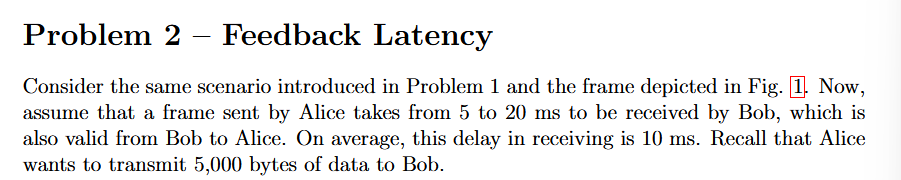

(a) What is the minimum time required by Alice to know that a frame has been lost? And the maximum?

Solution: 5ms+5ms (min) 20ms + 20ms(max) 🐐

(b) Assuming that all frames are received successfully, what is the average throughput in bit/s of Alice’s transmission by considering now the ACKs from Bob?

Solution: $\frac{536\mathrm{bits}\cdot 79\;\mathrm{frames}}{20\mathrm{ms}\cdot 79\;\mathrm{frames}}=26800\frac{\mathrm{bits}}{s}$

average_throughput = (536*79)/(20e-3*79);

**Consider now that Alice transmits 10,000 frames to Bob and assume that every 100-th frame is lost in transmission. Consider only that frames from Alice can be in error, while ACKs/NACKs are perfectly sent from Bob.**

(c) How many retransmissions would occur?

retransmission = (10e3/100) + 1 % Husk at retransmission som man regner fra 10e3/100 også fejler derfor + 1 :)

retransmission =    101


(d) How long would it take to transmit all frames on average? Assume that all retrans-mission is successful

Solution:


$$\frac{10100\;\mathrm{frames}\cdot 536\;\mathrm{bits}}{26\ldotp 8\mathrm{E3}\;\mathrm{averagethroughput}}=202\mathrm{sekunder}$$


average_transmit = (10100*536)/26.8e3;

Alternative answer:

(10e3+100)*20e-3; %Total frame gange average delaye for receive

ans =    202


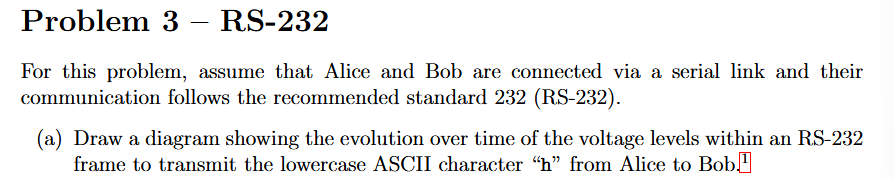

Solution: FUCKING TEGN :)

(b) Consider a baud rate of 9,600 bit/s. How long would it take for to Alice send the sentence “hello world” to Bob assuming error-free communication? Assume that each RS-232 frame is comprised of a start bit and a stop bit and that there are no parity bits.

x = (11*10)/(9600); % i sekunder for totalt mængde af karaktere(11) som fylder 10 bit
num2sip(x);

ans = '11.458 m'

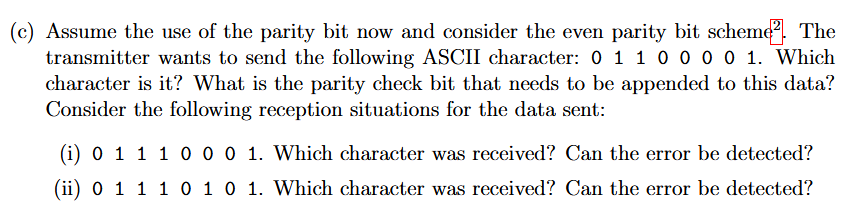

Solution: ACII = 'a' og paritiy bit = 1 grundet even parity hvilket medfører at man tæller antal '1' og da dette er ulige = 1 og modsat for hvis det var lige. For ulige parity så ville ulige antal 1 give 0 og omvendt.

    (i) q and yes.

    (ii) u and no, fordi det er lige parity og der er lige antal 1 så skulle det sidste bit være 0?

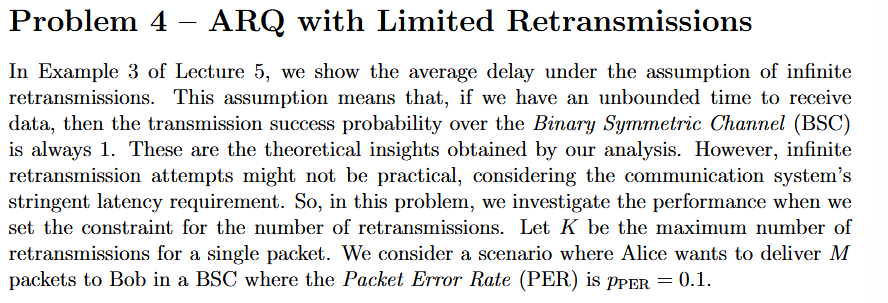

Solution:

$1-{\left(p_{\mathrm{PER}} \right)}^{\mathrm{Total}\;\mathrm{transmissions}\left(K+M\right)}$=$\mathrm{proability}\;\mathrm{of}\;\mathrm{succesful}\;\mathrm{transmission}$

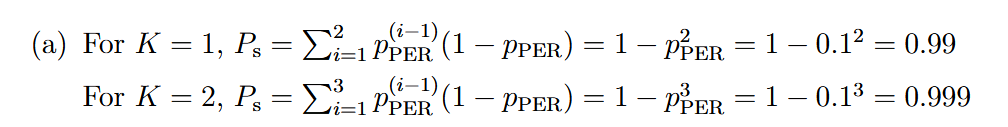

(b) Calculate the throughput for K = 1, and then for K = 2


$$\mathrm{Number}\;\mathrm{of}\;\mathrm{packet}\left(M\right)\cdot \frac{\mathrm{proability}\;\mathrm{of}\;\mathrm{succes}\;\mathrm{transmissions}}{\mathrm{number}\;\mathrm{of}\;\mathrm{transmissiomns}\left(M+K\right)}=1\cdot \frac{0\ldotp 99}{2}=0\ldotp 495\;\mathrm{packet}\;\mathrm{per}\;\mathrm{slot}$$



$$1\cdot \frac{0\ldotp 999}{3}=0\ldotp 333\;\mathrm{Packet}\;\mathrm{per}\;\mathrm{slot}$$


(c) Characterize the relationship between the throughput, the probability of successful packet transmission, and the value of K.

Solution: Increasing the number of retransmissions leads to a higher probability of successful packet transmission for a single packet, while it deteriorates the throughput. **TLDR**: Betal ved kasse 1 🐐🐐🐐🐐

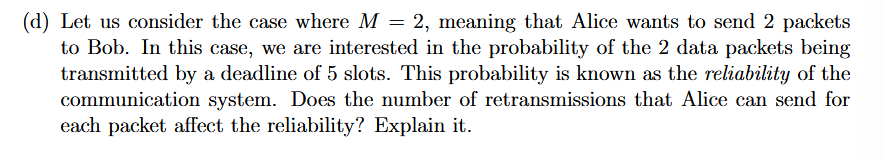

Solution:

If the set number of retransmissions makes the total number of transmissions for the 2 packets higher than 5 slots, then the reliability is zero.

Fx: M=2 og K=1 så hvis hver message fejler og en retransmission sker så det totalt 4 hvilket er under 5 slots hvilket er godt. Mere end det så er reliability zero.

Notice that the reliability also depends on Bob successfully receiving the data packets. Hence, if the total number of transmissions for the 2 packets is below 5 slots, the communication reliability is defined by the packet error rate.

## Lecture 6

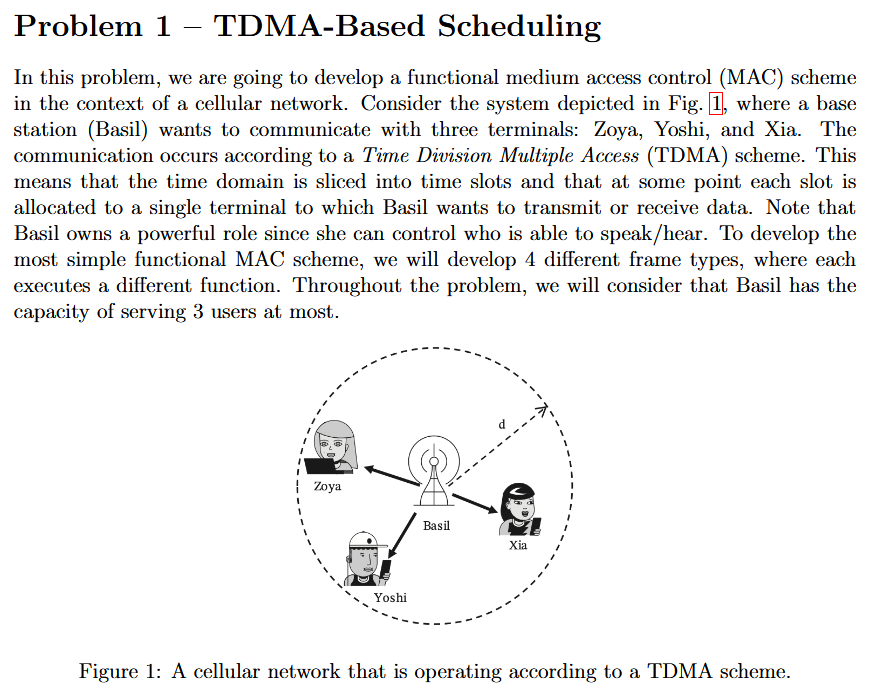

Solution: $\mathrm{log2}\left(4\right)\;$Hvor 4 er de forskellige different frame types.

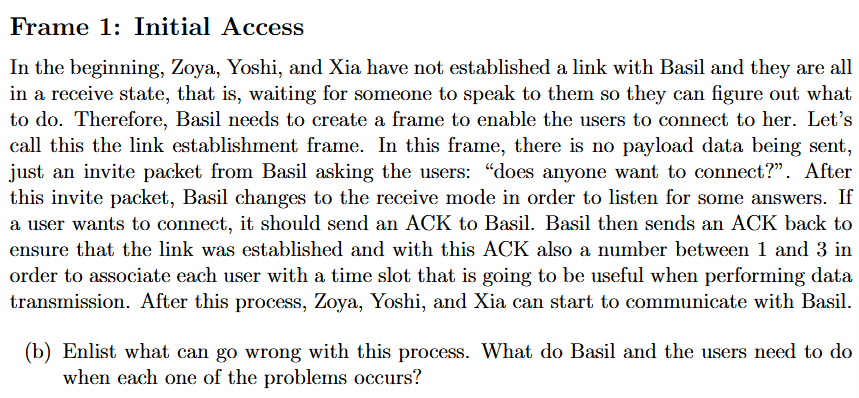

Solution: 

- Det kan gå galt hvis de alle gerne vil snak med Basil på samme tid og der sker ingen ting.

- ACK can be lost in transmission for both parties and nothing happens then try again to fix it :)

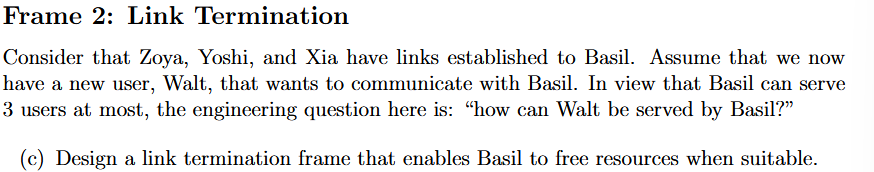

Solution:

Based on the initial access frame, a link termination frame would be comprised of a reference signal sent by Basil to establish that this frame has begun. Then, Basil sends the address of the user that she wants to be terminated. The user listens to it and withdraws its connection. The user no longer has access to the network. 🐐😸

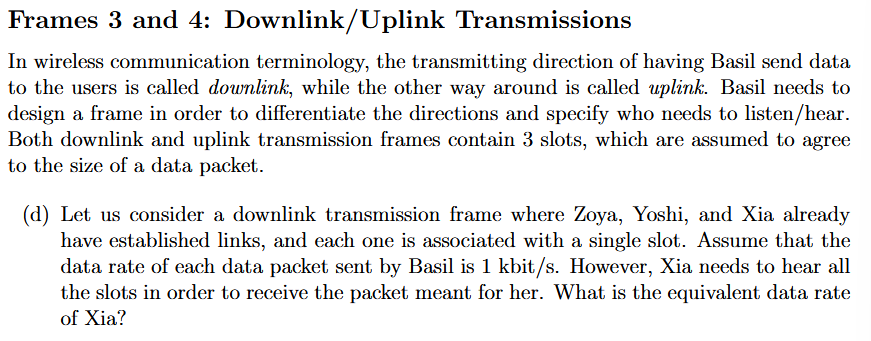

Solution: 1kbit /s bliver delt i mellem 3 som skal høre det hele

1e3/3;

ans =           333.333333333333


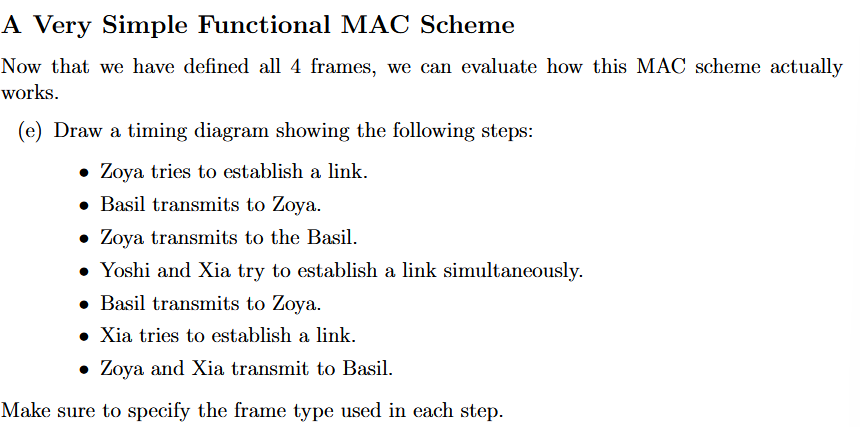

Solution: Jeg har lagt det på github og sæt billede ind.

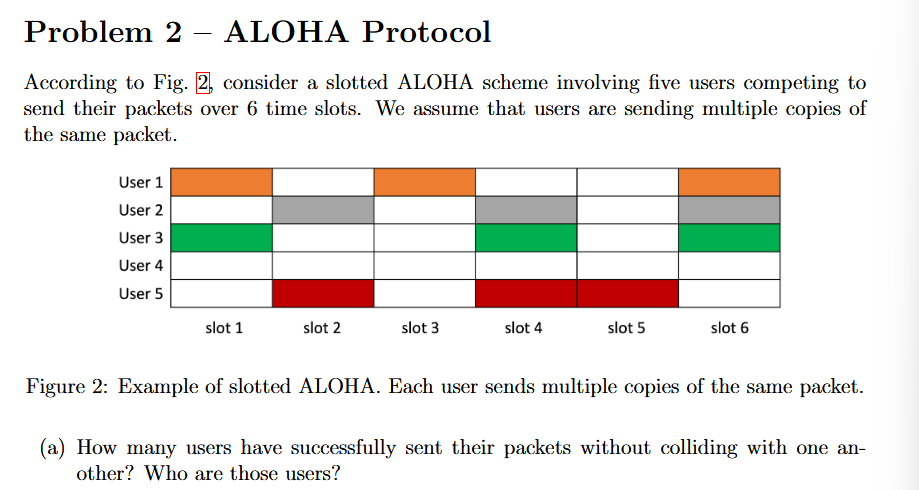

Solution:

User 1, Slot 3 and User 5 Slot 5

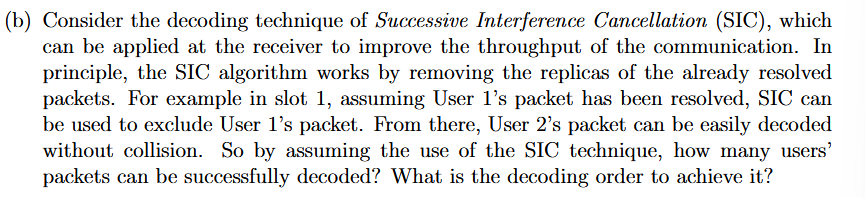

Solution:  U have to pick either slot 3 or slot 5 since there are only one package which means the sequence will either start with user 1 or user 5.

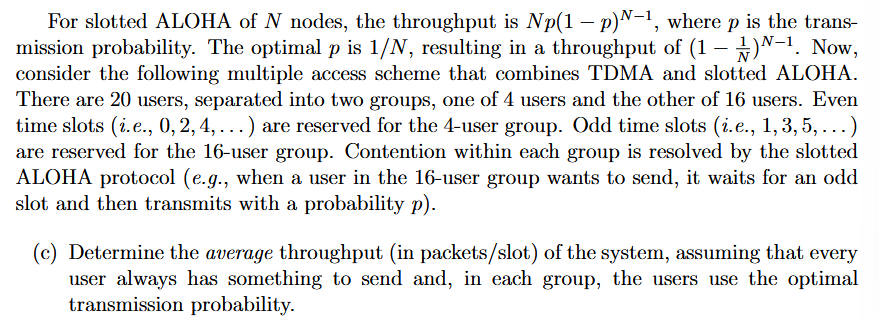

Solution:

$\frac{{\left(1-\frac{1}{4}\right)}^{4-1} +{\left(1-\frac{1}{16}\right)}^{\left(16-1\right)} }{2}=0\ldotp 4$ Brug formlen som er i givet i opgave beskrivelsen.

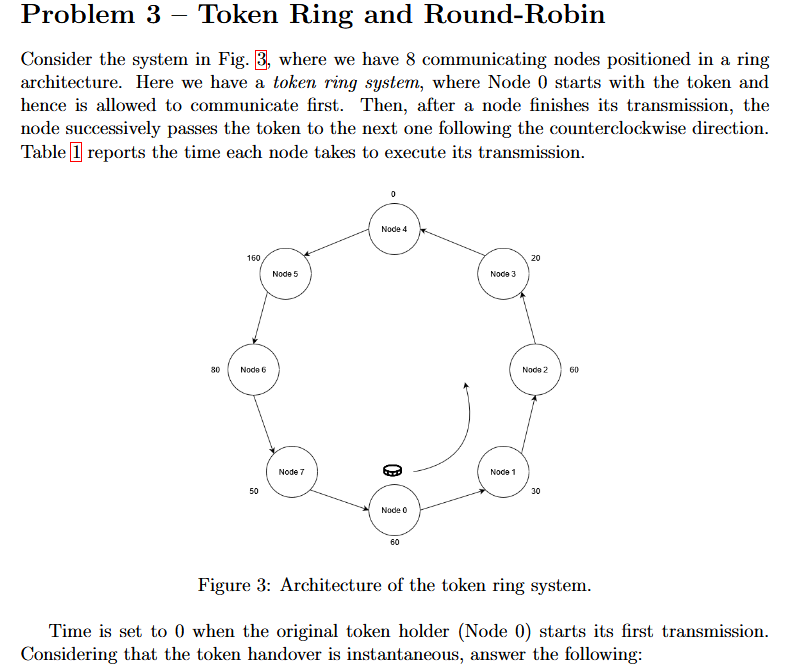

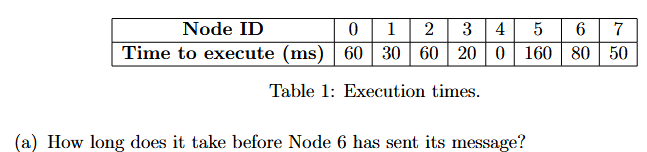

Solution:


$$60+30+60+20+0+160+80=410$$


Solution: Det betyder at en node kan bruge lang tid på at sende så rimelig unfair :)

Ingen garanti på latens for at kommunikere.

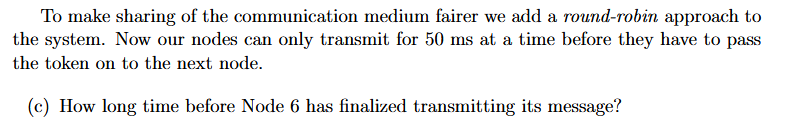

Solution: 50+30+50+20+50+50+50+10+10+50+30=400 (Så man skal to gange rund eftersom at 50 er maksimal det der kan sendes så der er en rest for nogen)

Solution:

- Increased: Node; 2,0,5

- Decreased: Node; 1,3,6,7

- Unchanged: Node; 4

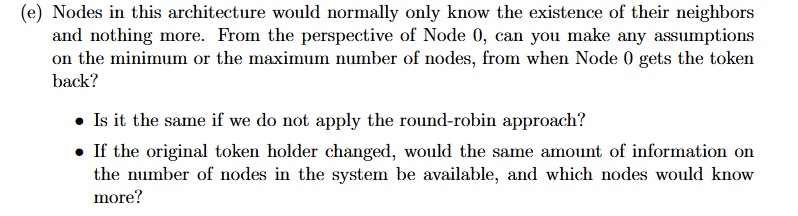

Solution:

If we think of time when doing a full circle of the ring, Node 0 may communicate again after 300 ms. If we consider the maximum time we may use the medium (50 ms), Node 0 knows at least 6 nodes are in the system since 300. If we consider the maximum time we may use the medium (50ms), Node 0 knows atleast 6 nodes are in the system since $\frac{300}{50}=6$

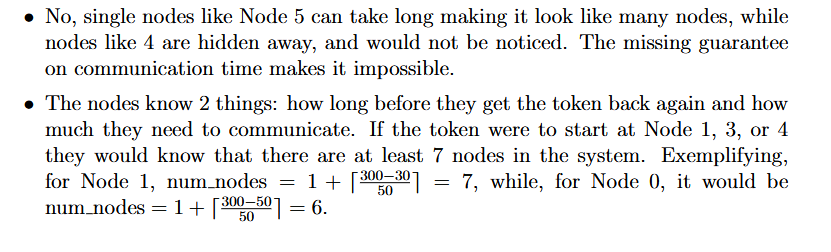

It wouldnt know, but with round robin it would since max delay time is implemented?

## Lecture 8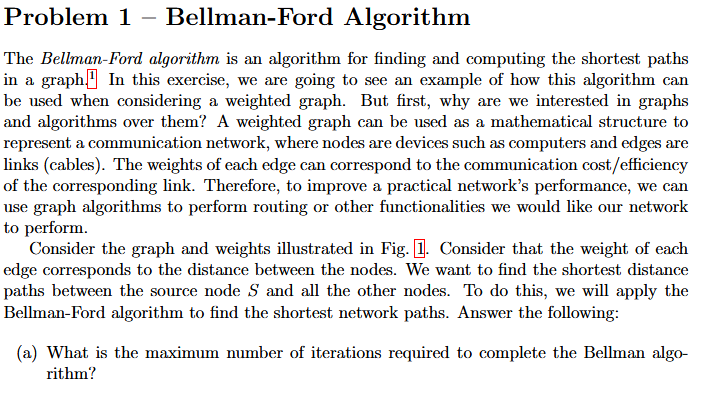

Solution: Number of vertices - 1 so it is 4

Solution:

 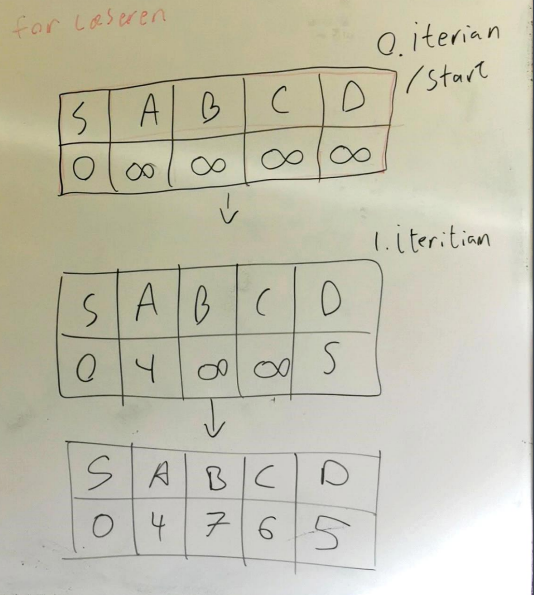

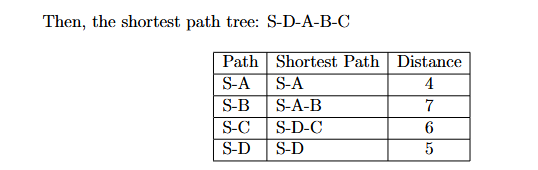

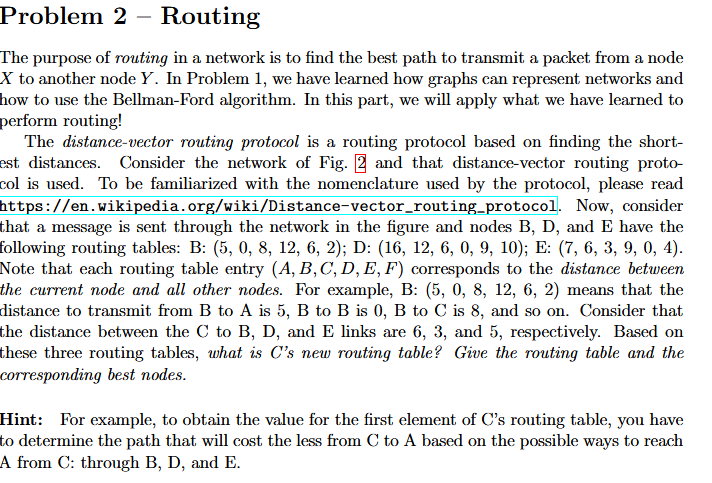

Solution:

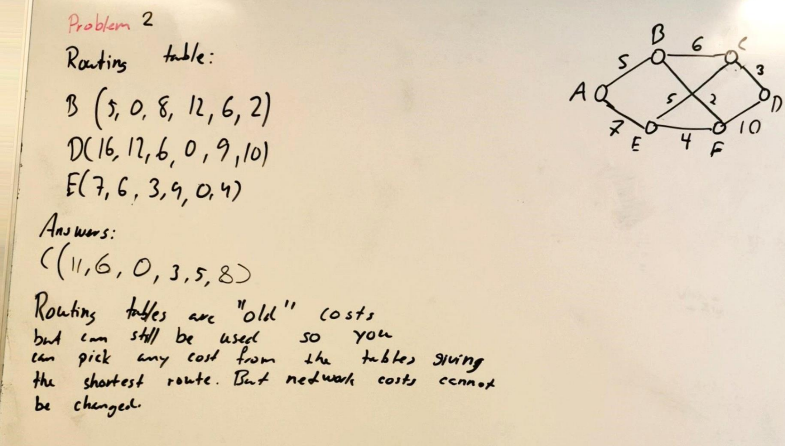

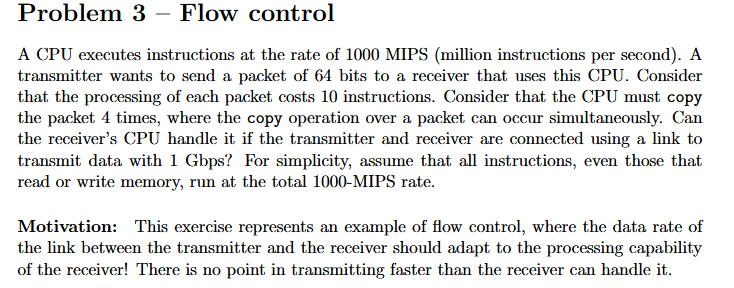

Solution:

Which is 40 instructions in 40 nanoseconds.

64 bits i pakken = 8 bytes:

$\frac{8}{40e-9}=5\textrm{nano}\;\textrm{sekund}$ for enkelt byte men vi har gigabitpersekund så derfor: $\frac{8\textrm{bit}}{5e-9\textrm{sekund}}=1600\frac{\textrm{gigabit}}{\textrm{sekund}}$ hvilket vil sige at den kan håndtere det eftersom det er større end 1 gigabit.

Egen solution fra github:

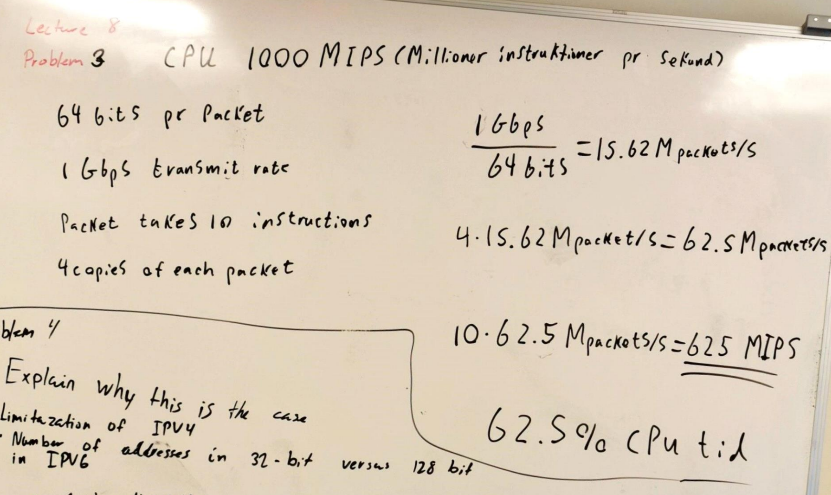

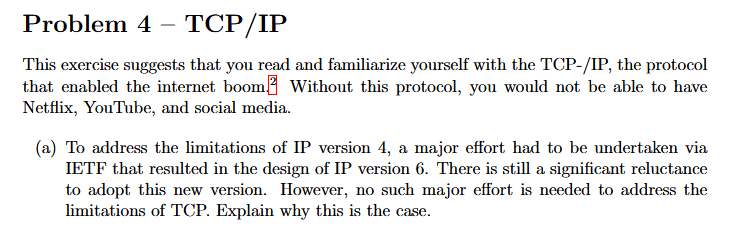

Solution: At der var for få addreser i IPV4 og derfor blev IPV6 lavet :)

Eftersom at TCP kan snakke sammen på forskellige versioner af sig selv men det kan IP (fordi det er fysisk) og derfor er det reluctance.

Solution:

Det tilføjer at man kan se om man bruger det 32bit acknowledge field.

Det spild hvis man nu ikke skal bruge feltet.

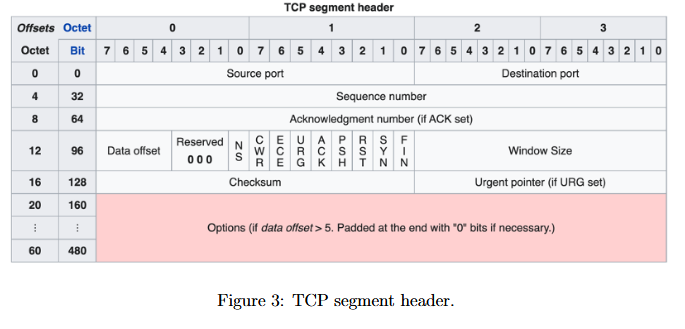

## Lecture 9

Solution: 

- ECB; Much data must not have patterns cause it can be decrypted then.

- CBC; Packet cannot be lost since decryption is then impossible for subsequent packages.

Solution: The receiver can only verify the message contents and the sender but not the transmitter can not verify anything.

But if they both send a message the receivers can decrypt the same thing iguees?.

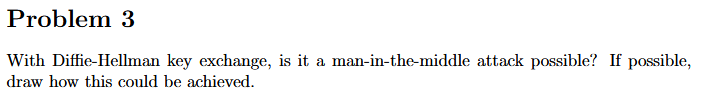

Solution: YES :)

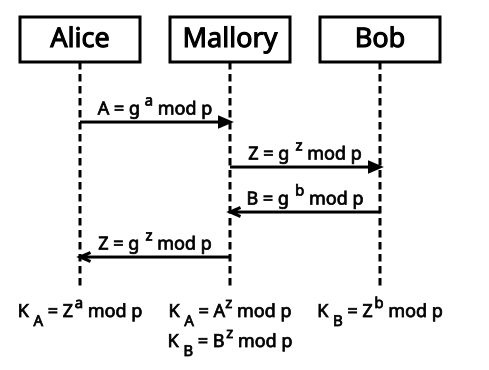

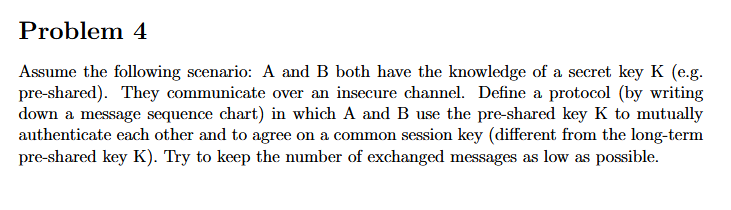

Solution: Held og lykke brormand :)

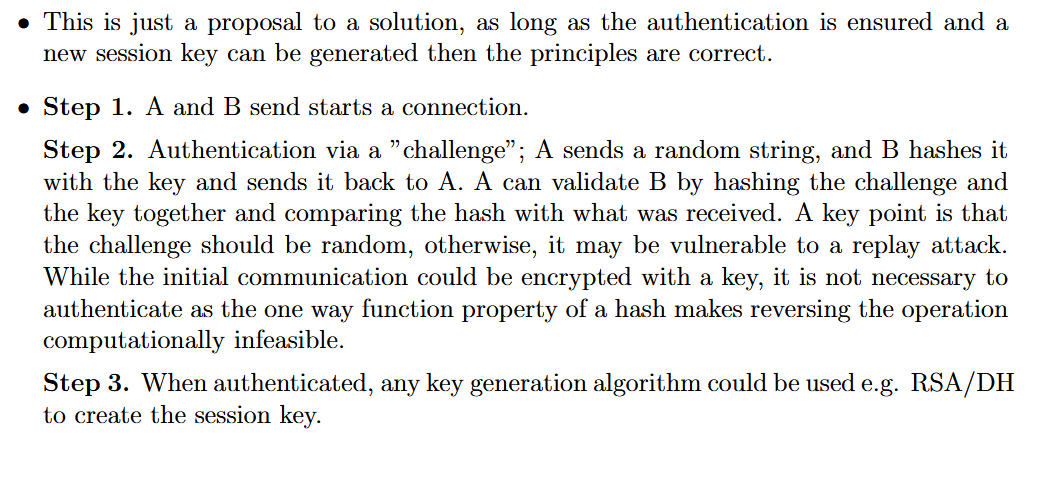

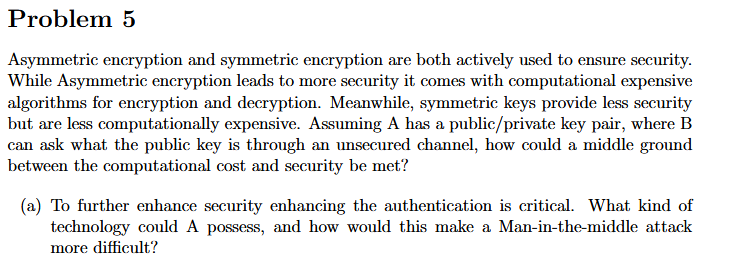

Man stoler på de certificates der kommer fra en authority 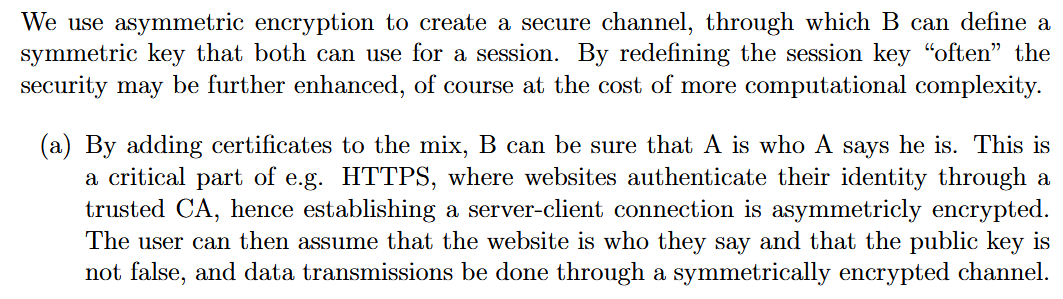

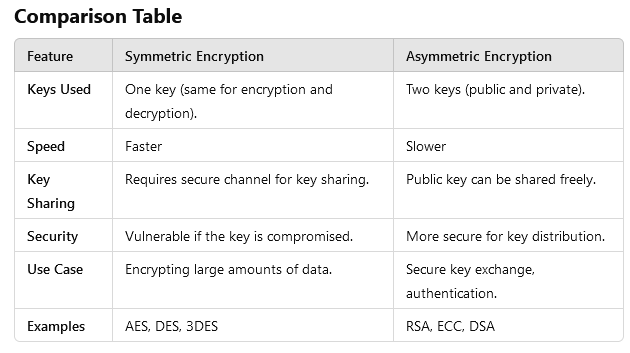

## Lecture 11

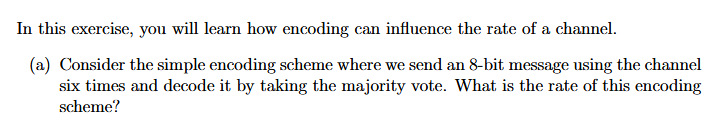

Solution: